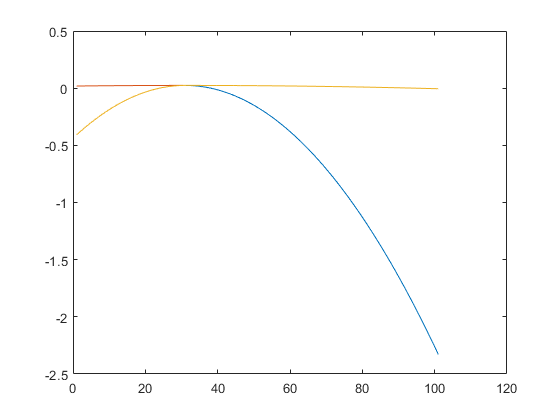

clear
syms r t u p xx r1 r2 r3 r4 t1 t2 t3 t4 u1 u2 u3 u4 p1 p2 p3 p4 l2 l3
x(1)=0;
x(2)=25;
x(3)=30;
x(4)=75;
x(5)=100;
y(1)=0.002;
%max=120%(x4-x2)
%y(3)=(1/(x(4)-x(2))*1.2);
y(3)=0.024;
%+90*0.00012;
%y(2)=(y(3)+1/(x(5)-x(1)))/2;
y(2)=y(3)/2;
%y(2)=0.019;
y(4)=y(2);
y(5)=y(1);
%y(5)=0.001;
step=0.1;
k=1;
x=x+1;
a(xx)=t1/(xx+u1)^2+p1;
s1(xx)=t2*xx^2+u2*xx+p2;
s2(xx)=t3*xx^2+u3*xx+p3;
d(xx)=t4/(xx+u4)^2+p4;
F=[a(xx) s1(xx) s2(xx) d(xx) ];

aa(xx)=diff(a(xx));
ss1(xx)=diff(s1(xx));
ss2(xx)=diff(s2(xx));
dd(xx)=diff(d(xx));
FF=[aa(xx) ss1(xx) ss2(xx) dd(xx) ];

for i=2:3
    D(xx)=F(i);
    E(k)=D(x(i))==y(i);
    k=k+1;
    E(k)=D(x(i+1))==y(i+1);
    k=k+1;
end
[u2, p2]=solve([E(1) E(2)], [u2 p2]);
[u3, p3]=solve([E(3) E(4)], [u3 p3]);
FF=eval(FF);
D(xx)=FF(2);
DD(xx)=FF(3);
EE(1)=D(x(3))==0;
EE(2)=DD(x(3))==0;
t2=solve([EE(1)],t2);
t3=solve([EE(2)],t3);
eval(EE);
s1(xx)=eval(s1(xx));
s1(xx)=eval(s1(xx));
s1(xx)=eval(s1(xx));
s2(xx)=eval(s2(xx));
s2(xx)=eval(s2(xx));
s2(xx)=eval(s2(xx));
s1(xx)=eval(s1(xx));
s2(xx)=eval(s2(xx));
aa(xx)=diff(a(xx));
ss1(xx)=diff(s1(xx));
ss2(xx)=diff(s2(xx));
dd(xx)=diff(d(xx));
FF=[aa(xx) ss1(xx) ss2(xx) dd(xx) ];
x1=(x(1):step:x(2));
x2=(x(2):step:x(3));
x3=(x(3):step:x(4));
x4=(x(4):step:x(5));
XA=(x(1):step:x(5));
X=[x1 x2 x3 x4];
Y=[s1(x1) s1(x2) s2(x3) s2(x4)];
plot(XA, s1(XA), XA, s2(XA), X, Y)

%plot(XA, ss1(XA), XA, ss2(XA))
g=1-(int(s1(xx),x(2),x(3))+int(s2(xx),x(3),x(4)))

$$g = \frac{10483}{540431955284459520000}$$

double(g)

ans = 1.9397e-17

sdvs

Unrecognized function or variable 'sdvs'.

clear E
k=1
D(xx)=F(1);
E(k)=D(x(1))==y(1);
k=k+1;
E(k)=D(x(2))==y(2);
k=k+1;
D(xx)=F(4);
E(k)=D(x(4))==y(4);
k=k+1;
E(k)=D(x(5))==y(5);
k=k+1;
E
[t1, p1]=solve([E(1) E(2)], [t1 p1])
[t4, p4]=solve([E(3) E(4)], [t4 p4])

FF=eval (FF)
clear E H
G(xx)=FF(1)
D(xx)=FF(2)
DD(xx)=FF(3)
H(xx)=FF(4)

E(1)=G(x(2))==D(x(2))
E(2)=G(x(1))==0
E(3)=H(x(4))==DD(x(4))
E(4)=H(x(5))==0

[u1]=solve([E(1)], [u1])
[u4]=solve([E(3)], [u4])
u1=u1(1)
u4=u4(2)
a(xx)=eval(eval (a(xx)))
d(xx)=eval(eval (d(xx)))
Y=[a(x1) s1(x2) s2(x3) d(x4)];
plot(XA, s1(XA), XA, s2(XA), XA, a(XA), XA, d(XA))
plot(X-1, Y)
w=int(a(xx),x(1),x(2))+int(s1(xx),x(2),x(3))+int(s2(xx),x(3),x(4))+int(d(xx),x(4),x(5))
double(w)

